# **Fourier Transfer**

**take a signal compioned with Fs = 1 MHz**

clear
clc
close all
Fs = 1000; % Hz
T = 4; % duration of the signal (period)
f0 = 50; % Hz

generate the signal

t = (0:1/Fs:T)';
x = sawtooth(2*pi*f0*t, 0.5);

draw the signal during the time

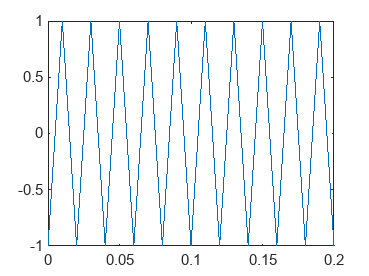

figure(1);
plot(t, x);
xlim([0 0.2]);

Now we calculate the Fourier Transform using the DFT

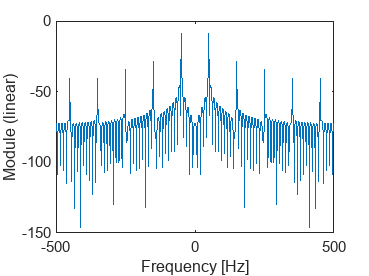

M = 4096;
X = fft(x, M)/M;
figure(2);
f = Fs/M*(0:M-1)';
plot(f-Fs/2, 20*log10(abs(fftshift(X))));
xlabel('Frequency [Hz]');
ylabel('Module (linear)');